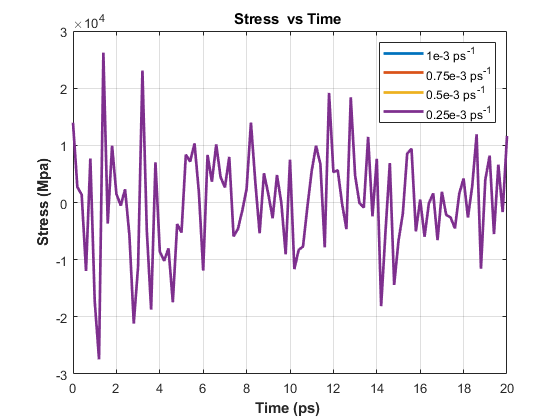

%%%swcnt
clc
clear all
close all


%%% fig 1 : Equilibration--time,etotal,pe,temp,pzz
%%%%% fig 2: deformation---time,etotal,pe,temp,strain,pzz

%%% C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (10,0)-60\CNT.10.0.60.300K.1.
CNT100Equ1 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (10,0)-60\CNT.10.0.60.300K.1.Equi.txt','r');
CNT100Def1 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (10,0)-60\CNT.10.0.60.300K.1.Deform.txt','r');
CNT100Equ75 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (10,0)-60\CNT.10.0.60.300K.75.Equi.txt','r');
CNT100Def75 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (10,0)-60\CNT.10.0.60.300K.75.Deform.txt','r');
CNT100Equ5 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (10,0)-60\CNT.10.0.60.300K.5.Equi.txt','r');
CNT100Def5 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (10,0)-60\CNT.10.0.60.300K.5.Deform.txt','r');
CNT100Equ25 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (10,0)-60\CNT.10.0.60.300K.25.Equi.txt','r');
CNT100Def25 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (10,0)-60\CNT.10.0.60.300K.25.Deform.txt','r');
CNT100Equ01 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (10,0)-60\CNT.10.0.60.300K.01.Equi.txt','r');
CNT100Def01 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (10,0)-60\CNT.10.0.60.300K.01.Deform.txt','r');

EquCNT1001 = cell2mat(textscan(CNT100Equ1,'%f%f%f%f%f','headerlines',1));
DefCNT1001 =cell2mat(textscan(CNT100Def1,'%f%f%f%f%f%f','headerlines',1));
EquCNT10075 = cell2mat(textscan(CNT100Equ75,'%f%f%f%f%f','headerlines',1));
DefCNT10075 =cell2mat(textscan(CNT100Def75,'%f%f%f%f%f%f','headerlines',1));
EquCNT1005 = cell2mat(textscan(CNT100Equ5,'%f%f%f%f%f','headerlines',1));
DefCNT1005 =cell2mat(textscan(CNT100Def5,'%f%f%f%f%f%f','headerlines',1));
EquCNT10025 = cell2mat(textscan(CNT100Equ25,'%f%f%f%f%f','headerlines',1));
DefCNT10025 =cell2mat(textscan(CNT100Def25,'%f%f%f%f%f%f','headerlines',1));
EquCNT10001 = cell2mat(textscan(CNT100Equ01,'%f%f%f%f%f','headerlines',1));
DefCNT10001 =cell2mat(textscan(CNT100Def01,'%f%f%f%f%f%f','headerlines',1));


fclose(CNT100Equ1);
fclose(CNT100Def1);
fclose(CNT100Equ75);
fclose(CNT100Def75);
fclose(CNT100Equ5);
fclose(CNT100Def5);
fclose(CNT100Equ25);
fclose(CNT100Def25);
fclose(CNT100Equ01);
fclose(CNT100Def01);

figure(1)  %%% equilibtration...stress vs time
plot(EquCNT1001(:,1),EquCNT1001(:,5),"LineWidth",2); 
hold on
plot(EquCNT10075(:,1),EquCNT10075(:,5),"LineWidth",2); 
hold on
plot(EquCNT1005(:,1),EquCNT1005(:,5),"LineWidth",2); 
hold on
plot(EquCNT10025(:,1),EquCNT10025(:,5),"LineWidth",2); 
hold on

title('Stress  vs Time ')
xlabel('Time (ps) ',"FontWeight","bold")
ylabel('Stress (Mpa)',"FontWeight","bold")
legend('1e-3 ps^{-1}','0.75e-3 ps^{-1}','0.5e-3 ps^{-1}','0.25e-3 ps^{-1}')
grid on

hold off

%%%%finding Sut...and yield strain
[Sut1,In1]= max(DefCNT1001(:,6));Ys1=DefCNT1001(In1,5);
[Sut2,In2]= max(DefCNT10075(:,6));Ys2=DefCNT10075(In2,5);
[Sut3,In3]= max(DefCNT1005(:,6));Ys3=DefCNT1005(In3,5);
[Sut4,In4]= max(DefCNT10025(:,6));Ys4=DefCNT10025(In4,5);
Sut_300= [Sut1 Sut2 Sut3 Sut4]'*1e-3;  % in Gpa
Ys_300= [Ys1 Ys2 Ys3 Ys4]'  % yield strain

Ys_300 =     0.1826
    0.1899
    0.1890
    0.1931


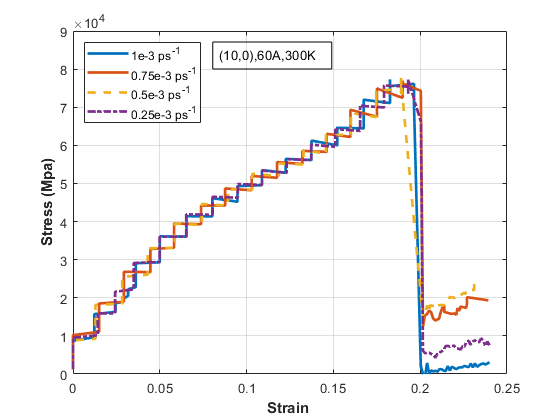


figure(2);   %deformation
plot(DefCNT1001(:,5),DefCNT1001(:,6),"LineWidth",2); % strain vs stress
hold on
plot(DefCNT10075(:,5),DefCNT10075(:,6),"LineWidth",2);
hold on
plot(DefCNT1005(:,5),DefCNT1005(:,6),'--',"LineWidth",2);
hold on
plot(DefCNT10025(:,5),DefCNT10025(:,6),'-.',"LineWidth",2);
hold on


title('')
xlabel('Strain ',"FontWeight","bold")
ylabel('Stress (Mpa)',"FontWeight","bold")
legend('1e-3 ps^{-1}','0.75e-3 ps^{-1}','0.5e-3 ps^{-1}','0.25e-3 ps^{-1}','Location','northwest')
grid on
xlim([0 0.25])
ylim([0 9]*1e4)
annotation('textbox', [0.38, 0.8, 0.1, 0.1], 'String', "(10,0),60A,300K",'FitBoxToText',"on")
saveas(gcf,'C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\Graphs\Stress_vs_strain_10060A300K.jpg')

 hold off

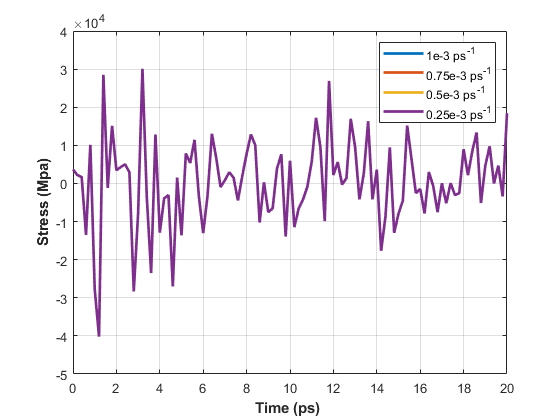



%%% fig 1 : Equilibration--time,etotal,pe,temp,pzz
%%%%% fig 2: deformation---time,etotal,pe,temp,strain,pzz

%%% C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (10,0)-60\CNT.10.0.60.800K
CNT100Equ1 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (10,0)-60\CNT.10.0.60.800K.1.Equi.txt','r');
CNT100Def1 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (10,0)-60\CNT.10.0.60.800K.1.Deform.txt','r');
CNT100Equ75 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (10,0)-60\CNT.10.0.60.800K.75.Equi.txt','r');
CNT100Def75 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (10,0)-60\CNT.10.0.60.800K.75.Deform.txt','r');
CNT100Equ5 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (10,0)-60\CNT.10.0.60.800K.5.Equi.txt','r');
CNT100Def5 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (10,0)-60\CNT.10.0.60.800K.5.Deform.txt','r');
CNT100Equ25 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (10,0)-60\CNT.10.0.60.800K.25.Equi.txt','r');
CNT100Def25 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (10,0)-60\CNT.10.0.60.800K.25.Deform.txt','r');
CNT100Equ01 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (10,0)-60\CNT.10.0.60.800K.01.Equi.txt','r');
CNT100Def01 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (10,0)-60\CNT.10.0.60.800K.01.Deform.txt','r');

EquCNT1001 = cell2mat(textscan(CNT100Equ1,'%f%f%f%f%f','headerlines',1));
DefCNT1001 =cell2mat(textscan(CNT100Def1,'%f%f%f%f%f%f','headerlines',1));
EquCNT10075 = cell2mat(textscan(CNT100Equ75,'%f%f%f%f%f','headerlines',1));
DefCNT10075 =cell2mat(textscan(CNT100Def75,'%f%f%f%f%f%f','headerlines',1));
EquCNT1005 = cell2mat(textscan(CNT100Equ5,'%f%f%f%f%f','headerlines',1));
DefCNT1005 =cell2mat(textscan(CNT100Def5,'%f%f%f%f%f%f','headerlines',1));
EquCNT10025 = cell2mat(textscan(CNT100Equ25,'%f%f%f%f%f','headerlines',1));
DefCNT10025 =cell2mat(textscan(CNT100Def25,'%f%f%f%f%f%f','headerlines',1));
EquCNT10001 = cell2mat(textscan(CNT100Equ01,'%f%f%f%f%f','headerlines',1));
DefCNT10001 =cell2mat(textscan(CNT100Def01,'%f%f%f%f%f%f','headerlines',1));


fclose(CNT100Equ1);
fclose(CNT100Def1);
fclose(CNT100Equ75);
fclose(CNT100Def75);
fclose(CNT100Equ5);
fclose(CNT100Def5);
fclose(CNT100Equ25);
fclose(CNT100Def25);
fclose(CNT100Equ01);
fclose(CNT100Def01);

figure(3)  %%% equilibtration...stress vs time
plot(EquCNT1001(:,1),EquCNT1001(:,5),"LineWidth",2); 
hold on
plot(EquCNT10075(:,1),EquCNT10075(:,5),"LineWidth",2); 
hold on
plot(EquCNT1005(:,1),EquCNT1005(:,5),"LineWidth",2); 
hold on
plot(EquCNT10025(:,1),EquCNT10025(:,5),"LineWidth",2); 
hold on

title('')
xlabel('Time (ps) ',"FontWeight","bold")
ylabel('Stress (Mpa)',"FontWeight","bold")
legend('1e-3 ps^{-1}','0.75e-3 ps^{-1}','0.5e-3 ps^{-1}','0.25e-3 ps^{-1}')
grid on

hold off

%%%%finding Sut...and yield strain
[Sut1,In1]= max(DefCNT1001(:,6));Ys1=DefCNT1001(In1,5);
[Sut2,In2]= max(DefCNT10075(:,6));Ys2=DefCNT10075(In2,5);
[Sut3,In3]= max(DefCNT1005(:,6));Ys3=DefCNT1005(In3,5);
[Sut4,In4]= max(DefCNT10025(:,6));Ys4=DefCNT10025(In4,5);
Sut_800= [Sut1 Sut2 Sut3 Sut4]'*1e-3;  % in Gpa
Ys_800= [Ys1 Ys2 Ys3 Ys4]'  % yield strain

Ys_800 =     0.1707
    0.1636
    0.1709
    0.1621


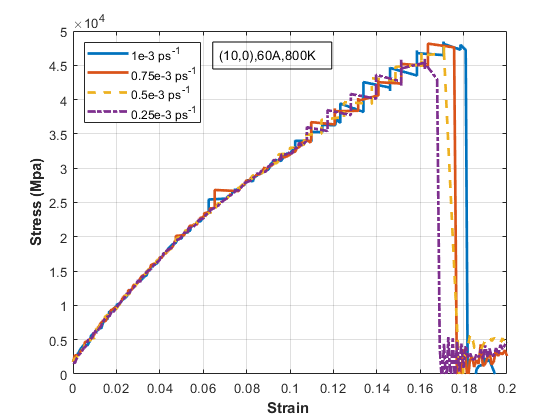

figure(4);   %deformation
plot(DefCNT1001(:,5),DefCNT1001(:,6),"LineWidth",2); % strain vs stress
hold on
plot(DefCNT10075(:,5),DefCNT10075(:,6),"LineWidth",2);
hold on
plot(DefCNT1005(:,5),DefCNT1005(:,6),'--',"LineWidth",2);
hold on
plot(DefCNT10025(:,5),DefCNT10025(:,6),'-.',"LineWidth",2);
hold on


title('')
xlabel('Strain ',"FontWeight","bold")
ylabel('Stress (Mpa)',"FontWeight","bold")
legend('1e-3 ps^{-1}','0.75e-3 ps^{-1}','0.5e-3 ps^{-1}','0.25e-3 ps^{-1}','Location','northwest')
grid on
xlim([0 0.2])
ylim([0 5]*1e4)
annotation('textbox', [0.38, 0.8, 0.1, 0.1], 'String', "(10,0),60A,800K",'FitBoxToText',"on")
saveas(gcf,'C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\Graphs\Stress_vs_Strain100800K.jpg')

hold off

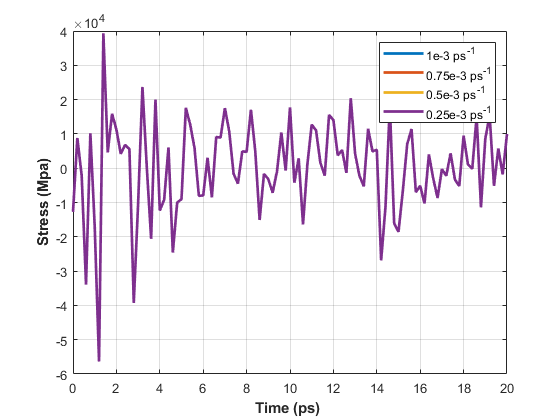


%%% fig 1 : Equilibration--time,etotal,pe,temp,pzz
%%%%% fig 2: deformation---time,etotal,pe,temp,strain,pzz

%%% C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (10,0)-60\CNT.10.0.60.1600K
CNT100Equ1 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (10,0)-60\CNT.10.0.60.1600K.1.Equi.txt','r');
CNT100Def1 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (10,0)-60\CNT.10.0.60.1600K.1.Deform.txt','r');
CNT100Equ75 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (10,0)-60\CNT.10.0.60.1600K.75.Equi.txt','r');
CNT100Def75 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (10,0)-60\CNT.10.0.60.1600K.75.Deform.txt','r');
CNT100Equ5 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (10,0)-60\CNT.10.0.60.1600K.5.Equi.txt','r');
CNT100Def5 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (10,0)-60\CNT.10.0.60.1600K.5.Deform.txt','r');
CNT100Equ25 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (10,0)-60\CNT.10.0.60.1600K.25.Equi.txt','r');
CNT100Def25 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (10,0)-60\CNT.10.0.60.1600K.25.Deform.txt','r');
CNT100Equ01 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (10,0)-60\CNT.10.0.60.1600K.01.Equi.txt','r');
CNT100Def01 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (10,0)-60\CNT.10.0.60.1600K.01.Deform.txt','r');


EquCNT1001 = cell2mat(textscan(CNT100Equ1,'%f%f%f%f%f','headerlines',1));
DefCNT1001 =cell2mat(textscan(CNT100Def1,'%f%f%f%f%f%f','headerlines',1));
EquCNT10075 = cell2mat(textscan(CNT100Equ75,'%f%f%f%f%f','headerlines',1));
DefCNT10075 =cell2mat(textscan(CNT100Def75,'%f%f%f%f%f%f','headerlines',1));
EquCNT1005 = cell2mat(textscan(CNT100Equ5,'%f%f%f%f%f','headerlines',1));
DefCNT1005 =cell2mat(textscan(CNT100Def5,'%f%f%f%f%f%f','headerlines',1));
EquCNT10025 = cell2mat(textscan(CNT100Equ25,'%f%f%f%f%f','headerlines',1));
DefCNT10025 =cell2mat(textscan(CNT100Def25,'%f%f%f%f%f%f','headerlines',1));
EquCNT10001 =cell2mat(textscan(CNT100Equ01,'%f%f%f%f%f','headerlines',1));
DefCNT10001 =cell2mat(textscan(CNT100Def01,'%f%f%f%f%f%f','headerlines',1));


fclose(CNT100Equ1);
fclose(CNT100Def1);
fclose(CNT100Equ75);
fclose(CNT100Def75);
fclose(CNT100Equ5);
fclose(CNT100Def5);
fclose(CNT100Equ25);
fclose(CNT100Def25);
fclose(CNT100Equ01);
fclose(CNT100Def01);

figure(5)  %%% equilibtration...stress vs time
plot(EquCNT1001(:,1),EquCNT1001(:,5),"LineWidth",2); 
hold on
plot(EquCNT10075(:,1),EquCNT10075(:,5),"LineWidth",2); 
hold on
plot(EquCNT1005(:,1),EquCNT1005(:,5),"LineWidth",2); 
hold on
plot(EquCNT10025(:,1),EquCNT10025(:,5),"LineWidth",2); 
hold on

title('')
xlabel('Time (ps) ',"FontWeight","bold")
ylabel('Stress (Mpa)',"FontWeight","bold")
legend('1e-3 ps^{-1}','0.75e-3 ps^{-1}','0.5e-3 ps^{-1}','0.25e-3 ps^{-1}')
grid on

hold off

%%%%finding Sut...and yield strain
[Sut1,In1]= max(DefCNT1001(:,6));Ys1=DefCNT1001(In1,5);
[Sut2,In2]= max(DefCNT10075(:,6));Ys2=DefCNT10075(In2,5);
[Sut3,In3]= max(DefCNT1005(:,6));Ys3=DefCNT1005(In3,5);
[Sut4,In4]= max(DefCNT10025(:,6));Ys4=DefCNT10025(In4,5);
Sut_1600= [Sut1 Sut2 Sut3 Sut4]'*1e-3;  % in Gpa
Ys_1600= [Ys1 Ys2 Ys3 Ys4]'  % yield strain

Ys_1600 =     0.1258
    0.1318
    0.1343
    0.1167


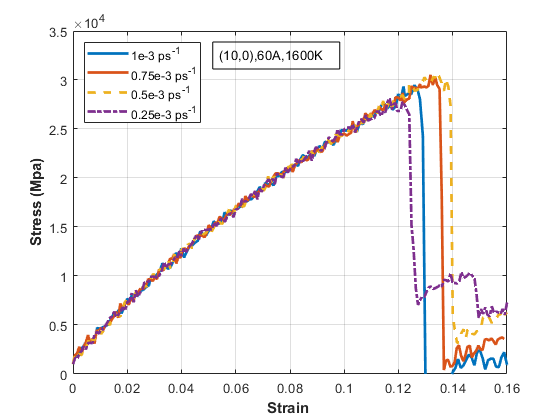


figure(6);   %deformation
plot(DefCNT1001(:,5),DefCNT1001(:,6),"LineWidth",2); % strain vs stress
hold on
plot(DefCNT10075(:,5),DefCNT10075(:,6),"LineWidth",2);
hold on
plot(DefCNT1005(:,5),DefCNT1005(:,6),'--',"LineWidth",2);
hold on
plot(DefCNT10025(:,5),DefCNT10025(:,6),'-.',"LineWidth",2);
hold on


title('')
xlabel('Strain ',"FontWeight","bold")
ylabel('Stress (Mpa)',"FontWeight","bold")
legend('1e-3 ps^{-1}','0.75e-3 ps^{-1}','0.5e-3 ps^{-1}','0.25e-3 ps^{-1}','Location','northwest')
grid on
xlim([0 0.16])
ylim([0 3.5]*1e4)
annotation('textbox', [0.38, 0.8, 0.1, 0.1], 'String', "(10,0),60A,1600K",'FitBoxToText',"on")
saveas(gcf,'C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\Graphs\Stress_vs_Strain1001600K.jpg')

hold off

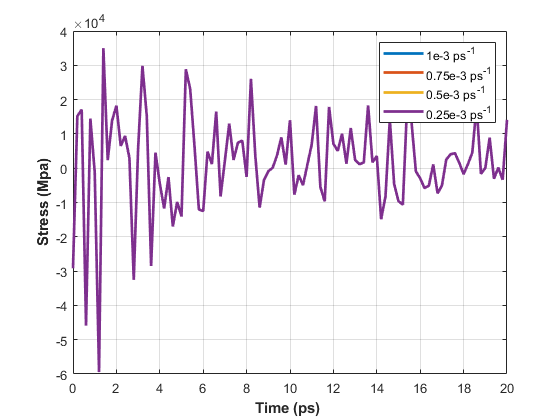

%%% C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (10,0)-60\CNT.10.0.60.2400K

%%% fig 1 : Equilibration--time,etotal,pe,temp,pzz
%%%%% fig 2: deformation---time,etotal,pe,temp,strain,pzz

%%% C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (10,0)-60\CNT.10.0.60.2400K
CNT100Equ1 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (10,0)-60\CNT.10.0.60.2400K.1.Equi.txt','r');
CNT100Def1 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (10,0)-60\CNT.10.0.60.2400K.1.Deform.txt','r');
CNT100Equ75 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (10,0)-60\CNT.10.0.60.2400K.75.Equi.txt','r');
CNT100Def75 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (10,0)-60\CNT.10.0.60.2400K.75.Deform.txt','r');
CNT100Equ5 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (10,0)-60\CNT.10.0.60.2400K.5.Equi.txt','r');
CNT100Def5 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (10,0)-60\CNT.10.0.60.2400K.5.Deform.txt','r');
CNT100Equ25 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (10,0)-60\CNT.10.0.60.2400K.25.Equi.txt','r');
CNT100Def25 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (10,0)-60\CNT.10.0.60.2400K.25.Deform.txt','r');
CNT100Equ01 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (10,0)-60\CNT.10.0.60.2400K.01.Equi.txt','r');
CNT100Def01 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (10,0)-60\CNT.10.0.60.2400K.01.Deform.txt','r');

EquCNT1001 = cell2mat(textscan(CNT100Equ1,'%f%f%f%f%f','headerlines',1));
DefCNT1001 =cell2mat(textscan(CNT100Def1,'%f%f%f%f%f%f','headerlines',1));
EquCNT10075 = cell2mat(textscan(CNT100Equ75,'%f%f%f%f%f','headerlines',1));
DefCNT10075 =cell2mat(textscan(CNT100Def75,'%f%f%f%f%f%f','headerlines',1));
EquCNT1005 = cell2mat(textscan(CNT100Equ5,'%f%f%f%f%f','headerlines',1));
DefCNT1005 =cell2mat(textscan(CNT100Def5,'%f%f%f%f%f%f','headerlines',1));
EquCNT10025 = cell2mat(textscan(CNT100Equ25,'%f%f%f%f%f','headerlines',1));
DefCNT10025 =cell2mat(textscan(CNT100Def25,'%f%f%f%f%f%f','headerlines',1));
EquCNT10001 = cell2mat(textscan(CNT100Equ01,'%f%f%f%f%f','headerlines',1));
DefCNT10001 =cell2mat(textscan(CNT100Def01,'%f%f%f%f%f%f','headerlines',1));


fclose(CNT100Equ1);
fclose(CNT100Def1);
fclose(CNT100Equ75);
fclose(CNT100Def75);
fclose(CNT100Equ5);
fclose(CNT100Def5);
fclose(CNT100Equ25);
fclose(CNT100Def25);
fclose(CNT100Equ01);
fclose(CNT100Def01);

figure(7)  %%% equilibtration...stress vs time
plot(EquCNT1001(:,1),EquCNT1001(:,5),"LineWidth",2); 
hold on
plot(EquCNT10075(:,1),EquCNT10075(:,5),"LineWidth",2); 
hold on
plot(EquCNT1005(:,1),EquCNT1005(:,5),"LineWidth",2); 
hold on
plot(EquCNT10025(:,1),EquCNT10025(:,5),"LineWidth",2); 
hold on

title('')
xlabel('Time (ps) ',"FontWeight","bold")
ylabel('Stress (Mpa)',"FontWeight","bold")
legend('1e-3 ps^{-1}','0.75e-3 ps^{-1}','0.5e-3 ps^{-1}','0.25e-3 ps^{-1}')
grid on

hold off

%%%%finding Sut...and yield strain
[Sut1,In1]= max(DefCNT1001(:,6));Ys1=DefCNT1001(In1,5);
[Sut2,In2]= max(DefCNT10075(:,6));Ys2=DefCNT10075(In2,5);
[Sut3,In3]= max(DefCNT1005(:,6));Ys3=DefCNT1005(In3,5);
[Sut4,In4]= max(DefCNT10025(:,6));Ys4=DefCNT10025(In4,5);
Sut_2400= [Sut1 Sut2 Sut3 Sut4]'*1e-3;  % in Gpa
Ys_2400= [Ys1 Ys2 Ys3 Ys4]';  % yield strain


Ys_100= [Ys_300,Ys_800,Ys_1600,Ys_2400]     %yield strain

Ys_100 =     0.1826    0.1707    0.1258    0.0995
    0.1899    0.1636    0.1318    0.0834
    0.1890    0.1709    0.1343    0.0924
    0.1931    0.1621    0.1167    0.0665


Sut_100= [Sut_300,Sut_800,Sut_1600,Sut_2400]       % young modulus (10,0)

Sut_100 =    77.3001   48.4784   29.4754   21.2166
   77.0019   48.1630   30.5163   18.8230
   77.7059   47.8081   30.8004   20.4500
   77.2104   45.9314   28.1527   16.0532


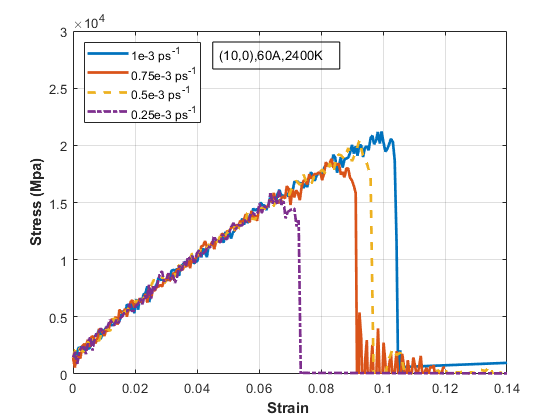

writematrix(Sut_100,'C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (10,0)-60\Sut_100.txt','Delimiter','tab')
writematrix(Ys_100,'C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (10,0)-60\Ys_100.txt','Delimiter','tab')


figure(8);   %deformation
plot(DefCNT1001(:,5),DefCNT1001(:,6),"LineWidth",2); % strain vs stress
hold on
plot(DefCNT10075(:,5),DefCNT10075(:,6),"LineWidth",2);
hold on
plot(DefCNT1005(:,5),DefCNT1005(:,6),'--',"LineWidth",2);
hold on
plot(DefCNT10025(:,5),DefCNT10025(:,6),'-.',"LineWidth",2);
hold on


title('')
xlabel('Strain ',"FontWeight","bold")
ylabel('Stress (Mpa)',"FontWeight","bold")
legend('1e-3 ps^{-1}','0.75e-3 ps^{-1}','0.5e-3 ps^{-1}','0.25e-3 ps^{-1}','Location','northwest')
grid on
xlim([0 0.14])
ylim([0 3]*1e4)
annotation('textbox', [0.38, 0.8, 0.1, 0.1], 'String', "(10,0),60A,2400K",'FitBoxToText',"on")
saveas(gcf,'C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\Graphs\Stress_vs_Strain1002400K.jpg')

hold off